# HW4 - Least Squares Kronecker Product Factorization  (LSKronF)

### Problem 1

Let us define the matrices

$\mathit{\mathbf{X}}\in C^{16\times 6}$, which can be stated as


$$\mathit{\mathbf{X}}=\mathit{\mathbf{A}}\otimes \mathit{\mathbf{B}}$$


where $\mathit{\mathbf{A}}\in C^{4\times 3}$ and $\mathit{\mathbf{B}}\in C^{4\times 2}$ are two unknown matrices, and $\otimes$ denotes the Kronecker Product.

The LSKronF is procedure that approximate $\mathit{\mathbf{X}}$ to $\hat{\mathit{\mathbf{A}}} \otimes \hat{\mathit{\mathbf{B}}}$, where $\hat{\mathit{\mathbf{A}}} \in C^{4\times 3}$ and $\hat{\mathit{\mathbf{B}}} \in C^{4\times 2}$ are the estimated values of $\mathit{\mathbf{A}}$ and $\mathit{\mathbf{B}}$, respectively.

The resulting matrices shall minimize the following cost function

${\left\|\mathit{\mathbf{X}}-\hat{\mathit{\mathbf{X}}} \right\|}_F^2$,

where $\hat{\mathit{\mathbf{X}}} =\hat{\mathit{\mathbf{A}}} \otimes \hat{\mathit{\mathbf{B}}}$ and ${\left\|\mathit{\mathbf{X}}\right\|}_F$ is the Frobenius norm of $\mathit{\mathbf{X}}$.

load kronf_matrix.mat X A B

Let us $\mathit{\mathbf{X}}$ be

X

X =     1.7013   -3.8298   -2.3937    5.3884    0.0631   -0.1420
    0.6726    0.6527   -0.9464   -0.9183    0.0249    0.0242
   -0.0693    0.7539    0.0976   -1.0606   -0.0026    0.0280
    0.8954   -0.6825   -1.2598    0.9603    0.0332   -0.0253
   -1.3142    2.9584    3.3404   -7.5195    0.2768   -0.6230
   -0.5196   -0.5042    1.3207    1.2815    0.1094    0.1062
    0.0536   -0.5823   -0.1361    1.4801   -0.0113    0.1226
   -0.6917    0.5272    1.7580   -1.3401    0.1457   -0.1110
    0.1551   -0.3491   -1.0720    2.4132   -0.1683    0.3788
    0.0613    0.0595   -0.4238   -0.4112   -0.0665   -0.0646


The $\tilde{\mathit{\mathbf{X}}}$ is gerenated following the procedure

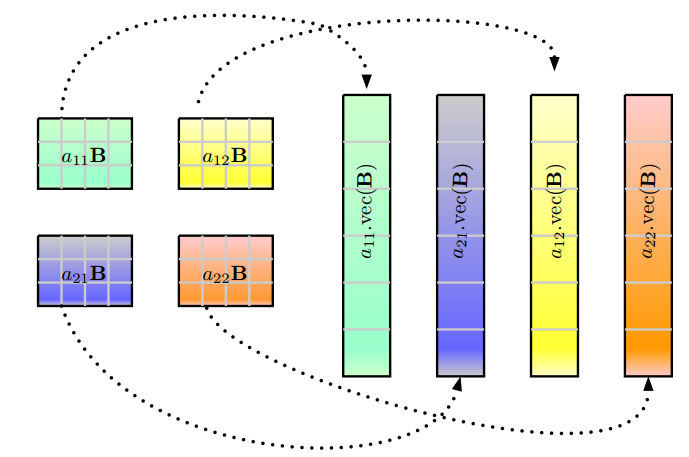

[m, n] = size(A);
[p, q] = size(B);
X_tilde = zeros(p*q, m*n);
X_tilde_column = 1;
for j = 0:n-1
    for i = 0:m-1
        block = X(1+i*p:(i+1)*p, 1+j*q:(j+1)*q);
        X_tilde(:, X_tilde_column) = reshape(block, [], 1);
        X_tilde_column = X_tilde_column + 1;
    end
end
X_tilde

X_tilde =     1.7013   -1.3142    0.1551   -0.5166   -2.3937    3.3404   -1.0720   -0.1985    0.0631    0.2768   -0.1683   -0.2155
    0.6726   -0.5196    0.0613   -0.2043   -0.9464    1.3207   -0.4238   -0.0785    0.0249    0.1094   -0.0665   -0.0852
   -0.0693    0.0536   -0.0063    0.0211    0.0976   -0.1361    0.0437    0.0081   -0.0026   -0.0113    0.0069    0.0088
    0.8954   -0.6917    0.0816   -0.2719   -1.2598    1.7580   -0.5642   -0.1045    0.0332    0.1457   -0.0886   -0.1134
   -3.8298    2.9584   -0.3491    1.1630    5.3884   -7.5195    2.4132    0.4469   -0.1420   -0.6230    0.3788    0.4850
    0.6527   -0.5042    0.0595   -0.1982   -0.9183    1.2815   -0.4112   -0.0762    0.0242    0.1062   -0.0646   -0.0827
    0.7539   -0.5823    0.0687   -0.2289   -1.0606    1.4801   -0.4750   -0.0880    0.0280    0.1226   -0.0746   -0.0955
   -0.6825    0.5272   -0.0622    0.2073    0.9603   -1.3401    0.4301    0.0796   -0.0253   -0.1110    0.0675    0.0864


Decomposing the matrix $\tilde{\mathit{\mathbf{X}}}$ into its singular values, we have

[U,S,V] = svd(X_tilde)

U =    -0.3778    0.7507   -0.3711   -0.0987   -0.3598   -0.0780    0.1031    0.0034
   -0.1494    0.1031    0.2410   -0.4125   -0.0703    0.5687   -0.6405    0.0128
    0.0154   -0.0169   -0.0429   -0.0450   -0.0057    0.0530    0.0343   -0.9958
   -0.1988    0.0949   -0.2708    0.5160    0.4475    0.6268    0.1352    0.0191
    0.8504    0.5007    0.0016    0.0243    0.1063    0.1088   -0.0477    0.0070
   -0.1449    0.2614    0.6188    0.6367   -0.1477   -0.1811   -0.2476   -0.0795
   -0.1674    0.2003   -0.1105   -0.1286    0.7339   -0.4657   -0.3824   -0.0376
    0.1516   -0.2393   -0.5778    0.3594   -0.3058   -0.1150   -0.5915   -0.0097


S =    12.7345         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000         0         0         0         0         0         0         0         0         0         0
         0         0    0.0000         0         0         0         0         0         0         0         0         0
         0         0         0    0.0000         0         0         0         0         0         0         0         0
         0         0         0         0    0.0000         0         0         0         0         0         0         0
         0         0         0         0         0    0.0000         0         0         0         0         0         0
         0         0         0         0         0         0    0.0000         0         0         0         0         0
         0         0         0         0         0         0         0    0.0000         0         0         0         0


V =    -0.3536    0.9132    0.1935    0.0242   -0.0091   -0.0332   -0.0353    0.0197   -0.0103    0.0065    0.0048    0.0060
    0.2732    0.1260   -0.1689    0.9018   -0.1378    0.0549    0.1298   -0.1285    0.0576    0.0280   -0.0162    0.0896
   -0.0322   -0.0179    0.1003    0.0163    0.0335    0.5098    0.1122    0.3268   -0.1400   -0.6087   -0.0861    0.4587
    0.1074    0.0433   -0.1842    0.1212   -0.0326    0.1218   -0.7903    0.3813   -0.2049   -0.0168   -0.1721   -0.2832
    0.4976    0.3370   -0.5574   -0.2775    0.4353    0.1550    0.1622   -0.0741    0.0291   -0.0188   -0.0560   -0.0377
   -0.6943   -0.1187   -0.6985    0.0745   -0.0017    0.0481    0.0516   -0.0253    0.0119    0.0089   -0.0327    0.0581
    0.2228    0.1400   -0.2624   -0.2878   -0.8591   -0.0021   -0.0154   -0.0360    0.0274   -0.0203    0.0785    0.1793
    0.0413    0.0013    0.0038   -0.0175    0.0331   -0.1269    0.1408    0.5115    0.0291    0.5774   -0.4145    0.4397
   -0.0131   -0.0029    0.01

Let us further define ${\mathit{\mathbf{v}}}_1$as the first column $\mathit{\mathbf{V}}$, that is

v1 = V(:,1);

The vectorization-form of the matrix $\hat{\mathit{\mathbf{A}}}$ is given by

sigma1 = S(1,1);
vecA = sqrt(sigma1) * v1;

Unvectorizing this vector, we have $\hat{\mathit{\mathbf{A}}} =\textrm{unvec}\left(\hat{\mathit{\mathbf{a}}} \right)\in C^{4\times 3}$

A_hat = reshape(vecA, [m, n]);

Let us define the ${\mathit{\mathbf{u}}}_1$ as the first column of $\mathit{\mathbf{U}}$, that is,

u1 = U(:,1);

The vectorization-form of the matrix $\hat{\mathit{\mathbf{B}}}$ is given by

vecB = sqrt(sigma1) * u1;

Unvectorizing this vector, we have $\hat{\mathit{\mathbf{B}}} =\textrm{unvec}\left(\hat{\mathit{\mathbf{b}}} \right)\in C^{4\times 2}$

B_hat = reshape(vecB, [p, q]);

### Comparisons

- $\left(\hat{\mathit{\mathbf{A}}} ,\hat{\mathit{\mathbf{B}}} \right)$vs$\left(\mathit{\mathbf{A}},\mathit{\mathbf{B}}\right)$

The matrices $\mathit{\mathbf{A}},\mathit{\mathbf{B}}$ are rather different from those estimated by the least-square Kronecker factorization. The matrix $\mathit{\mathbf{A}}$ is given by

A

A =     1.5211   -2.1402    0.0564
   -1.1750    2.9866    0.2475
    0.1386   -0.9585   -0.1505
   -0.4619   -0.1775   -0.1926


Whereas $\hat{\mathit{\mathbf{A}}}$is given by

A_hat

A_hat =    -1.2620    1.7756   -0.0468
    0.9749   -2.4778   -0.2053
   -0.1150    0.7952    0.1248
    0.3832    0.1473    0.1598


The normalized squared error of the estimation of $\mathit{\mathbf{A}}$ is


$$\frac{{\left\|\mathit{\mathbf{A}}-\hat{\mathit{\mathbf{A}}} \right\|}_F^2 }{{\left\|\mathit{\mathbf{A}}\right\|}_F^2 }$$


norm(A_hat - A,'fro')/norm(A,'fro')

ans = 1.8296

The matrix $\mathit{\mathbf{B}}$ is given by

B

B =     1.1185   -2.5178
    0.4422    0.4291
   -0.0456    0.4956
    0.5886   -0.4487


Whereas $\hat{\mathit{\mathbf{B}}}$ is given by

B_hat

B_hat =    -1.3481    3.0348
   -0.5330   -0.5172
    0.0549   -0.5974
   -0.7095    0.5408


The normalized squared error of the estimation of $\mathit{\mathbf{B}}$ is


$$\frac{{\left\|\mathit{\mathbf{B}}-\hat{\mathit{\mathbf{B}}} \right\|}_F^2 }{{\left\|\mathit{\mathbf{B}}\right\|}_F^2 }$$


norm(B_hat - B,'fro')/norm(B_hat,'fro')

ans = 1.8296

- $\mathit{\mathbf{X}}$ vs. $\hat{\mathit{\mathbf{X}}}$

On the other hand, the final matrix, $\hat{\mathit{\mathbf{X}}}$, gives an exact approximation of $\mathit{\mathbf{X}}$. The matrix $\hat{\mathit{\mathbf{X}}}$ is given by

X_hat = kron(A_hat, B_hat)

X_hat =     1.7013   -3.8298   -2.3937    5.3884    0.0631   -0.1420
    0.6726    0.6527   -0.9464   -0.9183    0.0249    0.0242
   -0.0693    0.7539    0.0976   -1.0606   -0.0026    0.0280
    0.8954   -0.6825   -1.2598    0.9603    0.0332   -0.0253
   -1.3142    2.9584    3.3404   -7.5195    0.2768   -0.6230
   -0.5196   -0.5042    1.3207    1.2815    0.1094    0.1062
    0.0536   -0.5823   -0.1361    1.4801   -0.0113    0.1226
   -0.6917    0.5272    1.7580   -1.3401    0.1457   -0.1110
    0.1551   -0.3491   -1.0720    2.4132   -0.1683    0.3788
    0.0613    0.0595   -0.4238   -0.4112   -0.0665   -0.0646


And the matrix $\mathit{\mathbf{X}}$is

X

X =     1.7013   -3.8298   -2.3937    5.3884    0.0631   -0.1420
    0.6726    0.6527   -0.9464   -0.9183    0.0249    0.0242
   -0.0693    0.7539    0.0976   -1.0606   -0.0026    0.0280
    0.8954   -0.6825   -1.2598    0.9603    0.0332   -0.0253
   -1.3142    2.9584    3.3404   -7.5195    0.2768   -0.6230
   -0.5196   -0.5042    1.3207    1.2815    0.1094    0.1062
    0.0536   -0.5823   -0.1361    1.4801   -0.0113    0.1226
   -0.6917    0.5272    1.7580   -1.3401    0.1457   -0.1110
    0.1551   -0.3491   -1.0720    2.4132   -0.1683    0.3788
    0.0613    0.0595   -0.4238   -0.4112   -0.0665   -0.0646


The normalize cost function is given by $\frac{{\left\|\mathit{\mathbf{X}}-\hat{\mathit{\mathbf{X}}} \right\|}_F^2 }{{\left\|\mathit{\mathbf{X}}\right\|}_F^2 }$

nmse = norm(X_hat - X,'fro')/norm(X,'fro')

nmse = 6.2543e-16

#### Conclusion

It is possible to notice that X can be decomposed into different matrices (A and B). The LSKronF is an efficient factorization procedure able to break $\mathit{\mathbf{X}}$ into two matrices that generates $\mathit{\mathbf{X}}$ again through the Kronecker product. However, the LSKronF can't find the original values (A and B) that originated X.

### Problem 2

Let us define

${\mathit{\mathbf{X}}}_0 =\mathit{\mathbf{A}}\otimes \mathit{\mathbf{B}}\in C^{\textrm{IJ}\times \textrm{PQ}}$,

where $\mathit{\mathbf{A}}\in C^{I\times P}$ and $\mathit{\mathbf{B}}\in C^{J\times Q}$ and complex matrix whose elements come from a normal distribution with mean equal to 0 and variance equal to 1, that is (assuming $I=2,\;J=4$),

i_set = [2, 4];
j_set = [4, 8];
p = 3;
q = 5;

A = randn([2,4]);
B = randn([p,q]);

X0 = kron(A,B)

X0 =     0.4004   -0.6536    0.6737   -0.6280   -0.2109   -1.0297    1.6806   -1.7323    1.6149    0.5423   -0.1746    0.2850   -0.2938    0.2739    0.0920    0.9707   -1.5844    1.6331   -1.5224   -0.5112
    0.7634   -0.9852    1.3217    0.0625   -0.0770   -1.9630    2.5333   -3.3986   -0.1607    0.1979   -0.3329    0.4297   -0.5764   -0.0273    0.0336    1.8506   -2.3883    3.2040    0.1515   -0.1866
    0.1318   -0.8953    0.3291   -1.6660    0.6277   -0.3389    2.3020   -0.8463    4.2839   -1.6139   -0.0575    0.3904   -0.1435    0.7266   -0.2737    0.3195   -2.1702    0.7978   -4.0386    1.5215
    0.3182   -0.5193    0.5353   -0.4990   -0.1676    0.1098   -0.1791    0.1847   -0.1721   -0.0578    0.1104   -0.1802    0.1857   -0.1731   -0.0581    0.0756   -0.1234    0.1272   -0.1186   -0.0398
    0.6066   -0.7828    1.0502    0.0497   -0.0612    0.2092   -0.2700    0.3623    0.0171   -0.0211    0.2104   -0.2716    0.3644    0.0172   -0.0212    0.1442   -0.1861    0.2496    0.0118 

Consider a noisy term, $\mathit{\mathbf{V}}$, is same dimension of ${\mathit{\mathbf{X}}}_0$, whose components come from a normal distribution with the same statistics. Let us define $\mathit{\mathbf{X}}={\mathit{\mathbf{X}}}_0 +\alpha \mathit{\mathbf{V}}$as the noisy term of ${\mathit{\mathbf{X}}}_0$, where $\alpha$ is a parameter that is setted depending on the signal-to-noise ration in the system, given by


$${\mathrm{SNR}}_{\mathrm{dB}} =10\;\log_{10} \;\left(\frac{{\left\|{\mathit{\mathbf{X}}}_0 \right\|}_F^2 }{{\left\|\alpha \mathit{\mathbf{V}}\right\|}_F^2 }\right)\to \alpha =\sqrt{{10}^{-\frac{{\mathrm{SNR}}_{\mathrm{dB}} }{10}} }$$


Let us suppose the ${\textrm{SNR}}_{\textrm{dB}} =0$, that is $\alpha =1$. Therefore, in this situation, the estimates $\hat{\mathit{\mathbf{A}}}$ and $\hat{\mathit{\mathbf{B}}}$ obtained with the LSKronF algorithm is given by

V = randn(size(X0));
X = X0 + V;

[A_hat, B_hat] = lskf(X,[2, 4])

A_hat =     0.6821   -2.7477   -0.9506    1.6355
    0.6959    0.0909    0.1301   -0.0459


B_hat =     0.7019   -0.9236    0.9949   -0.6593    0.0719
    0.6173   -0.9381    1.4474    0.1717    0.1344
    0.2966   -0.9041    0.4642   -1.9473    1.0069


And the estimated matrix, given by $\hat{\mathit{\mathbf{X}}} =\hat{\mathit{\mathbf{A}}} \otimes \hat{\mathit{\mathbf{B}}}$ is

X_hat = kron(A_hat,B_hat)

X_hat =     0.4788   -0.6300    0.6786   -0.4497    0.0490   -1.9287    2.5377   -2.7336    1.8115   -0.1975   -0.6673    0.8779   -0.9457    0.6267   -0.0683    1.1480   -1.5104    1.6271   -1.0782    0.1175
    0.4211   -0.6399    0.9874    0.1171    0.0917   -1.6961    2.5776   -3.9772   -0.4718   -0.3694   -0.5868    0.8917   -1.3760   -0.1632   -0.1278    1.0095   -1.5342    2.3672    0.2808    0.2199
    0.2023   -0.6168    0.3166   -1.3283    0.6869   -0.8149    2.4843   -1.2754    5.3506   -2.7667   -0.2819    0.8595   -0.4413    1.8511   -0.9572    0.4851   -1.4787    0.7591   -3.1847    1.6468
    0.4885   -0.6427    0.6924   -0.4588    0.0500    0.0638   -0.0840    0.0904   -0.0599    0.0065    0.0913   -0.1202    0.1295   -0.0858    0.0094   -0.0322    0.0424   -0.0457    0.0303   -0.0033
    0.4296   -0.6528    1.0073    0.1195    0.0936    0.0561   -0.0853    0.1316    0.0156    0.0122    0.0803   -0.1221    0.1883    0.0223    0.0175   -0.0283    0.0431   -0.0664   -0.00

This procedure is repeated for the SNR range $\left\lbrack 0,5,10,15,20,25,30\right\rbrack$ and for the configurations $\left(I,J,P,Q\right)=\left(2,4,3,5\right)$ and $\left(I,J,P,Q\right)=\left(4,8,3,5\right)$. The normalized mean square error (NMSE), given by


$$\textrm{NMSE}=\frac{1}{1000}\sum_i \frac{{\left\|\mathit{\mathbf{X}}\left(i\right)-\hat{\mathit{\mathbf{X}}} \left(i\right)\right\|}_F^2 }{{\left\|\mathit{\mathbf{X}}\left(i\right)\right\|}_F^2 }\;,$$


is obtained after 1000 Monte Carlo experiments. The matrices $\mathit{\mathbf{A}}$, $\mathit{\mathbf{B}}$, and $\mathit{\mathbf{V}}$ are randomly generated for each experiement.

max = 1e3;

snr_set = 0:5:30;
all_nmse = zeros(length(i_set), length(snr_set));
for i=i_set
        for snr=snr_set
            nmse = 0;
            for k=1:1e3
                A = randn([i,p]);
                B = randn([j_set(i_set==i),q]);
                X0 = kron(A,B);
                alpha = sqrt(10^(-snr/10));
                V = randn(size(X0));
                X = X0 + alpha*V;

                [A_hat, B_hat] = lskf(X,size(A));
                X_hat = kron(A_hat, B_hat);
                nmse = nmse + norm(X_hat - X0,'fro')/norm(X0,'fro');
            end
            all_nmse(i_set==i, snr_set==snr) = nmse/1e3;
        end
end

#### Ploting the results

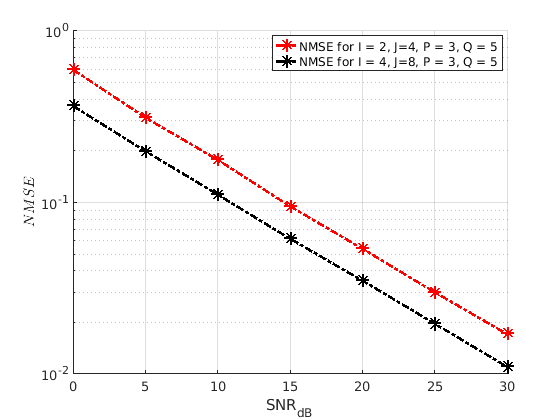

text_I = ["2","4"];
text_J = ["4","8"];
color_set = ["red", "black"];
fig = figure();
ax = gca();
ax.FontName = 'Times New Roman';
ax.FontSize = 20;
ax.YAxis.Scale='log';
ax.XAxis.Label.String = 'SNR_{dB}';
ax.YAxis.Label.String = '$$NMSE$$';
ax.YAxis.Label.Interpreter = 'latex';
grid on;
hold on;
for i=1:2
    plot(snr_set, all_nmse(i,:), 'LineWidth', 4, 'Color', color_set(i),"LineStyle","-.","Marker","*","MarkerSize",18);
end
legend([append("NMSE for I = ", text_I(1), ", J=", text_J(1), ", P = 3, Q = 5"), append("NMSE for I = ", text_I(2), ", J=", text_J(2), ", P = 3, Q = 5")]);
hold off;